## Set up the Import Options and import the data

clear; clc;
opts = delimitedTextImportOptions("NumVariables", 26);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = " ";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22", "VarName23", "VarName24", "VarName25", "VarName26"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";
opts.LeadingDelimitersRule = "ignore";

% Import the data
% training data
trainFD001 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\train_FD001.txt", opts);
trainFD002 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\train_FD002.txt", opts);
trainFD003 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\train_FD003.txt", opts);
trainFD004 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\train_FD004.txt", opts);

% testing data
testFD001 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\test_FD001.txt", opts);
testFD002 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\test_FD002.txt", opts);
testFD003 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\test_FD003.txt", opts);
testFD004 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\test_FD004.txt", opts);

% RUL for testing data
RULFD001 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\RUL_FD001.txt", opts);
RULFD002 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\RUL_FD002.txt", opts);
RULFD003 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\RUL_FD003.txt", opts);
RULFD004 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\RUL_FD004.txt", opts);


## Convert to output type

trainFD001 = table2array(trainFD001);
trainFD002 = table2array(trainFD002);
trainFD003 = table2array(trainFD003);
trainFD004 = table2array(trainFD004);

testFD001 = table2array(testFD001);
testFD002 = table2array(testFD002);
testFD003 = table2array(testFD003);
testFD004 = table2array(testFD004);

RULFD001 = table2array(RULFD001);
RULFD002 = table2array(RULFD002);
RULFD003 = table2array(RULFD003);
RULFD004 = table2array(RULFD004);

## Clear temporary variables

clear opts
varN = ["VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22", "VarName23", "VarName24", "VarName25", "VarName26"];

X1 = trainFD001 ; X2 = trainFD002; X3 = trainFD003; X4 = trainFD004;
X1(:,1:6)=[]; X2(:,1:6)=[]; X3(:,1:6)=[]; X4(:,1:6)=[];

model(1).data = trainFD001; model(2).data = trainFD002; model(3).data = trainFD003; model(4).data = trainFD004;
model(1).X = X1; model(2).X = X2; model(3).X = X3; model(4).X = X4;
model(1).y = GetRUL(trainFD001); model(2).y = GetRUL(trainFD002); model(3).y = GetRUL(trainFD003); model(4).y = GetRUL(trainFD004);

model(1).test = testFD001; model(2).test = testFD002; model(3).test = testFD003; model(4).test = testFD004;
model(1).RUL = RULFD001(:,1); model(2).RUL = RULFD002(:,1); model(3).RUL = RULFD003(:,1); model(4).RUL = RULFD004(:,1);


### **Exploratory Data Analysis**

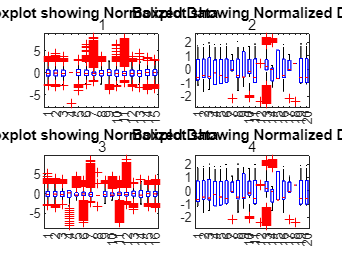

% Create summary stats table for each training dataset.
for i = 1:4
    model(i).summary = CreateSummary(model(i).X, varN);
end

% Plot a box plot for each.
figure;
for i = 1:4
    subplot(2,2,i)
    boxplot(model(i).X)
    title('Boxplot showing Original Data ',num2str(i))
end

Remove single value columns from the data

for i = 1:4
    model(i).single_col = [];
    k = 1;
    for j = 1:length(model(i).X(1,:))
        if round(model(i).summary{j,"SD"},5) == 0
            model(i).single_col(k) = j;
            k = k+1;
        end
    end
    model(i).X(:,model(i).single_col) = [];
end


Normalize and revisualize

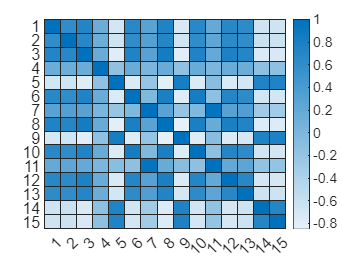

% Normalize each
for i = 1:4
    [model(i).Xnorm, model(i).C, model(i).S] = normalize(model(i).X);
end

% Plot a box plot for each normalized data.
figure;
for i = 1:4
    subplot(2,2,i)
    boxplot(model(i).Xnorm)
    title('Boxplot showing Normalized Data ',num2str(i))
end

Studying relationships between individual columns and the rul for a given number of units or any given unit. Code commented out because it takes long to run.

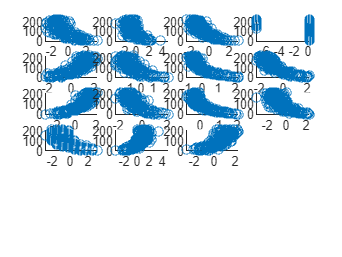

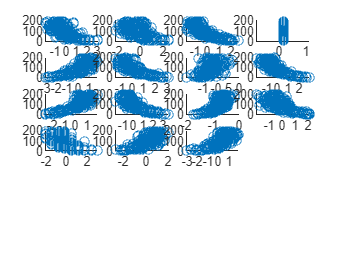

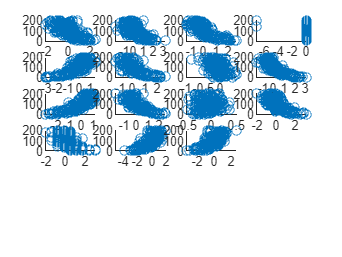

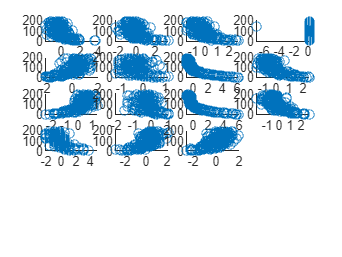

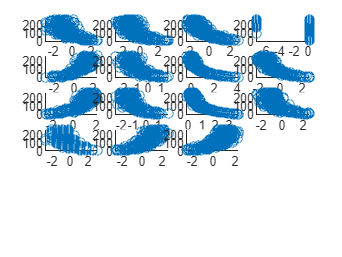

for i = 1:4
    model(i).unitnum = unique(model(i).data(:,1));
end


for unit = [1 4 5 100 10]
    figure;
    title(['Relationship between X and y for unit ', num2str(unit)]);
    [id1, ~] = find(model(1).data(:,1)==unit);
    for i = 1:length(model(1).X(1,:))
        subplot(6, 4, i)
        scatter(model(1).Xnorm(id1,i), model(1).y(id1))
    end
end


figure;
correlation = corr(model(1).Xnorm,model(1).Xnorm)

correlation =     1.0000    0.6026    0.7149    0.1322   -0.7021    0.6623    0.2738    0.7400   -0.7246    0.6618    0.1798    0.6760    0.6299   -0.6618   -0.6681
    0.6026    1.0000    0.6784    0.1160   -0.6646    0.6025    0.3230    0.6959   -0.6803    0.6010    0.2371    0.6399    0.6000   -0.6259   -0.6339
    0.7149    0.6784    1.0000    0.1505   -0.7931    0.7469    0.2974    0.8301   -0.8156    0.7452    0.1907    0.7585    0.7035   -0.7481   -0.7452
    0.1322    0.1160    0.1505    1.0000   -0.1557    0.1522    0.0193    0.1600   -0.1559    0.1583   -0.0021    0.1490    0.1308   -0.1414   -0.1374
   -0.7021   -0.6646   -0.7931   -0.1557    1.0000   -0.7671   -0.2178   -0.8228    0.8127   -0.7646   -0.1101   -0.7471   -0.6929    0.7362    0.7374
    0.6623    0.6025    0.7469    0.1522   -0.7671    1.0000   -0.0321    0.7822   -0.7865    0.8261   -0.1448    0.7009    0.6278   -0.6870   -0.6888
    0.2738    0.3230    0.2974    0.0193   -0.2178   -0.0321    1.0000    0.2746

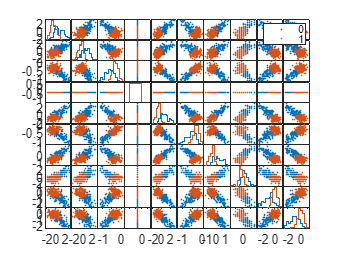

heatmap(correlation)

% for j=1:4
%     figure;
%     for i = 1:length(model(j).X(1,:))
%         subplot(6, 4, i)
%         scatter(model(j).X(:,i), model(j).y)
%     end
% end


Is there any variable which characterises the early lifetime and later life time of a TurboFan Engine?

for i = 1:4
    for unit  = 1 %model(i).unitnum
        k=0;
        [id1, ~] = find(model(i).data(:,1)==unit);
        for j = 1:length(model(i).Xnorm(1,k+1:unit))
            model(i).early_life = model(i).y > mean(model(i).y) + 0;
        end
        k = k + unit;
    end
end

figure;
title('Relationship between some important pairs of variables and early life')
gplotmatrix(model(3).Xnorm(id1,[1 2 5 8 9 10 11 14 15 16]), [], model(3).early_life(id1));

PCA to see if there are any faulty data, especially for dataset 2 (-_-) ...because why are you so strange?

% [earlyidx, ~] = find(model(3).early_life==1);
% [lateidx, ~] = find(model(3).early_life==0);
% 
% healthy_ = model(3).X(earlyidx, :);
% [healthy, C, S] = zscore(healthy_);
% 
% faulty_ = model(3).X(lateidx, :);
% faulty = normalize(faulty_, "center", C, "scale", S);
% Compute PCA for healthy dataset
% [P, T, latent, tsq, expl] = ...
%     pca(healthy, 'Centered', false, 'NumComponents', 8);
% 
% [Pf, Tf, latentf, tsqf, explf] = ...
%     pca(faulty, 'Centered', false, 'NumComponents', 8);
% 
% 
% figure;
% a = plot(1:10, 100*cumsum(expl(1:10))/sum(expl(1:10)));
% hold on
% b = plot(1:10, 100*cumsum(explf(1:10))/sum(explf(1:10)));
% hold off
% legend([a, b], 'healthy','faulty')
% 
% figure;
% i = 7;
% subplot(1,2,1);
% biplot(P(:,i:i+1), 'Scores', T(:,i:i+1));
% subplot(1,2,2)
% biplot(Pf(:,i:i+1), 'Scores', Tf(:,i:i+1));


PLS regression with Cross Validation inside

% % Define the desire number of folds for k-fold cross validation
% k = 4;
% 
% % gather all units for the dataset into an array
% units = unique(model(1).data(:,1));
% 
% % calculate the estimated number of units there should be in 1 fold.
% nfu = round(length(units)/k);
% ncomp=10;
% % divide the data into k folds, normalize and perform pls regression, then
% % fit the validation data and get the error of the model. 
% % in for loop, we calculate the estimate given one fold so we need to
% % calculate the total error after, meaning we probably step out of the for
% % loop for that.
% for i = 1:4
% 
%     for m = 1:ncomp
% 
%         for j = 1:k
%             [model(i).ncomp(m).kfold(j).testidx,~] = find(model(i).data((j-1)*nfu+1:nfu*j,1));
%             model(i).ncomp(m).kfold(j).trainidx = setdiff(units, model(i).ncomp(m).kfold(j).testidx);
%             model(i).ncomp(m).kfold(j).train = model(i).data(model(i).ncomp(m).kfold(j).trainidx,7:end);
%             model(i).ncomp(m).kfold(j).test = model(i).data(model(i).ncomp(m).kfold(j).testidx,7:end);
%             model(i).ncomp(m).kfold(j).ytrain = model(i).y(model(i).ncomp(m).kfold(j).trainidx);
%             model(i).ncomp(m).kfold(j).ytest = model(i).y(model(i).ncomp(m).kfold(j).testidx);
%             [model(i).ncomp(m).kfold(j).train, C, S] = zscore(model(i).ncomp(m).kfold(j).train);
%             model(i).ncomp(m).kfold(j).test = normalize(model(i).ncomp(m).kfold(j).test, "center", C, "scale", S);
% 
%             [~, ~, ~, ~, model(i).ncomp(m).kfold(j).beta, ...
%                     model(i).ncomp(m).kfold(j).MSE, ...
%                     model(i).ncomp(m).kfold(j).stats] = plsregress(model(i).ncomp(m).kfold(j).train, model(i).ncomp(m).kfold(j).ytrain, m);
% 
%             % Calculate R2
%             model(i).ncomp(m).kfold(j).Yfit    = [ones(size(model(i).ncomp(m).kfold(j).test,1),1) model(i).ncomp(m).kfold(j).test] * model(i).ncomp(m).kfold(j).beta;
%             model(i).ncomp(m).kfold(j).TSSRes  = sum((model(i).ncomp(m).kfold(j).ytest - mean(model(i).ncomp(m).kfold(j).ytest)).^2);
%             model(i).ncomp(m).kfold(j).RSSRes  = sum((model(i).ncomp(m).kfold(j).ytest - Yfit).^2);
%             model(i).ncomp(m).R2 = 1 - RSSRes / TSSRes;
% 
%             % Calculate Q2
%             YfitT   = [ones(size(model(i).ncomp(m).kfold(j).test,1),1) model(i).ncomp(m).kfold(j).test] * model(i).ncomp(m).kfold(j).beta;
%             PRESS = sum((model(i).ncomp(m).kfold(j).ytest - YfitT).^2);
%             model(i).ncomp(m).Q2 = 1 - PRESS / TSSRes;
% 
%             % Storing for later 
%             Beta(:,m) = model(i).ncomp(m).kfold(j).beta;
%         end
%         model(i).ncomp(m).R2 = mean(model(i).ncomp(m).R2)
%     end
% end


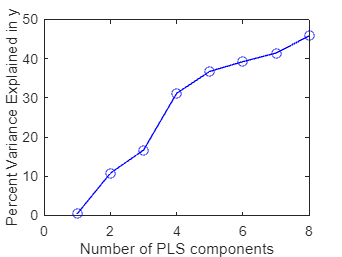

% Define the desired number of folds for k-fold cross-validation
k = 4;

% Gather all units for the dataset into an array
units = unique(model(1).data(:, 1));

% Calculate the estimated number of units there should be in 1 fold.
nfu = round(length(units) / k);
ncomp = 8;

% Initialize arrays to store R2 and Q2 values
R2_values = zeros(ncomp, k);
Q2_values = zeros(ncomp, k);

for i = 1:4
    
    for m = 1:ncomp
        
        for j = 1:k
            % Define train and test indices
            trainidx = setdiff(units, units((j-1)*nfu+1:nfu*j));
            testidx = units((j-1)*nfu+1:nfu*j);
            
            % Extract train and test data
            train = model(i).data(ismember(model(i).data(:, 1), trainidx), 7:end);
            test = model(i).data(ismember(model(i).data(:, 1), testidx), 7:end);
            ytrain = model(i).y(ismember(model(i).data(:, 1), trainidx));
            ytest = model(i).y(ismember(model(i).data(:, 1), testidx));

            % Z-score normalization
            [train, C, S] = zscore(train);
            test = normalize(test, 'center', C, 'scale', S);

            train(isnan(train))   = 0;
            test(isnan(test)) = 0;
            % Center the Y-matrices
                % Calibration
            ytrain       = ytrain - mean(ytrain);
                % Test
            Yt      = ytest - mean(ytest);
            

            % PLS regression
            [~, ~, ~, ~, beta, pctvar,MSE, stats] = plsregress(train, ytrain, m);

            % Calculate R2
            Yfit = [ones(size(test, 1), 1) test] * beta;
            TSSRes = sum((ytest - mean(ytest)).^2);
            RSSRes = sum((ytest - Yfit).^2);
            R2_value = 1 - RSSRes / TSSRes; % Use a different variable name for the scalar value
            model(i).R2_values(m, j) = R2_value;

            % Calculate Q2
            YfitT = [ones(size(test, 1), 1) test] * beta;
            PRESS = sum((ytest - YfitT).^2);
            Q2_value = 1 - PRESS / TSSRes; % Use a different variable name for the scalar value
            model(i).Q2_values(m, j) = Q2_value;

            
        end        
    end
end
figure;
plot(1:8,cumsum(100*pctvar(2,:)),'-bo')
xlabel('Number of PLS components');
ylabel('Percent Variance Explained in y');

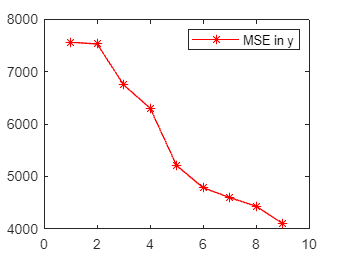

ans =    -0.0107
    0.0312
    0.1074
    0.2428
    0.3254
    0.4528
    0.4800
    0.5040



figure;
plot(1:9, MSE(2,:), "r*-")
legend("MSE in y")

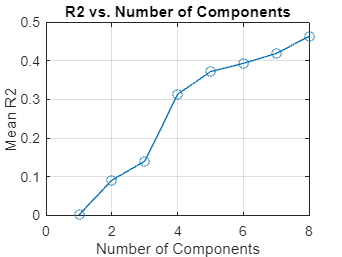

% Plot R2 values
figure;
plot(1:8, mean(model(4).R2_values, 2), '-o'); % Use the mean of the R2_values array instead of the struct field
title('R2 vs. Number of Components');
xlabel('Number of Components');
ylabel('Mean R2');
grid on;

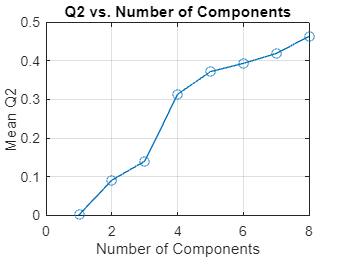


% Plot Q2 values
figure;
plot(1:8, mean(model(4).Q2_values, 2), '-o'); % Use the mean of the Q2_values array instead of the struct field
title('Q2 vs. Number of Components');
xlabel('Number of Components');
ylabel('Mean Q2');
grid on;